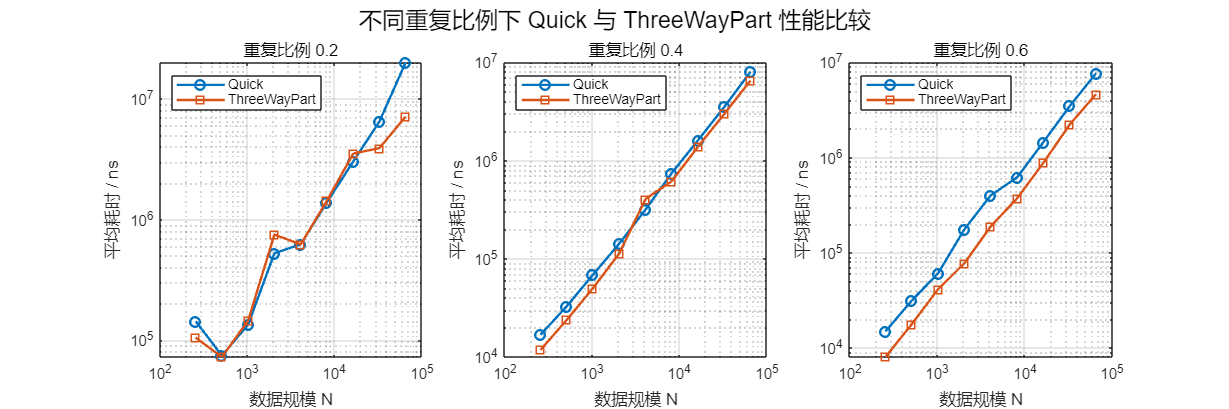

% 数据规模
N = [256 512 1024 2048 4096 8192 16384 32768 65536];

% 数据
Quick_02 = [143620 74440 134600 525440 622780 1390080 3023300 6499680 20097200];
ThreeWay_02 = [104920 72520 145080 751260 621940 1433840 3522780 3915880 7151560];

Quick_04 = [16840 32840 68860 142800 316920 746100 1613920 3519340 8037260];
ThreeWay_04 = [11800 23880 50300 113200 405900 617660 1386760 2988440 6538040];

Quick_06 = [14860 31380 60680 176380 401020 618540 1456740 3484500 7696900];
ThreeWay_06 = [8000 17720 41240 77600 189060 372360 882340 2228740 4649020];

% 调整 figure 宽度和高度（单位像素）
figure('Position',[100 100 1500 500]);  % 左下角X,Y，宽1500，高500

% 子图 1 - 重复比例 0.2
subplot(1,3,1);
loglog(N, Quick_02, '-o','LineWidth',1.5,'DisplayName','Quick'); hold on;
loglog(N, ThreeWay_02, '-s','LineWidth',1.5,'DisplayName','ThreeWayPart');
xlabel('数据规模 N'); ylabel('平均耗时 / ns'); title('重复比例 0.2');
legend('Location','northwest'); grid on;

% 子图 2 - 重复比例 0.4
subplot(1,3,2);
loglog(N, Quick_04, '-o','LineWidth',1.5,'DisplayName','Quick'); hold on;
loglog(N, ThreeWay_04, '-s','LineWidth',1.5,'DisplayName','ThreeWayPart');
xlabel('数据规模 N'); ylabel('平均耗时 / ns'); title('重复比例 0.4');
legend('Location','northwest'); grid on;

% 子图 3 - 重复比例 0.6
subplot(1,3,3);
loglog(N, Quick_06, '-o','LineWidth',1.5,'DisplayName','Quick'); hold on;
loglog(N, ThreeWay_06, '-s','LineWidth',1.5,'DisplayName','ThreeWayPart');
xlabel('数据规模 N'); ylabel('平均耗时 / ns'); title('重复比例 0.6');
legend('Location','northwest'); grid on;

sgtitle('不同重复比例下 Quick 与 ThreeWayPart 性能比较');